# Exercise 4

clear all;close all;clc;

## A

R = diag([1,1,1]);
t1 = [0;0;0];
t2 = [-5;0;2];
p1 = [2;4;10;1];
p2 = [2;4;20;1];
q11 = project(p1, R, t1)

q11 =     0.2000
    0.4000
    1.0000


q12 = project(p1, R, t2)

q12 =    -0.2500
    0.3333
    1.0000


q21 = project(p2, R, t1)

q21 =     0.1000
    0.2000
    1.0000


q22 = project(p2, R, t2)

q22 =    -0.1364
    0.1818
    1.0000


## D

v1 = [-0.166667;1/3;1];
v2 = [9.5;0.2857;-3];
A = v1*20.66/46.49;
B = [-5;0;2]+v2*24/46.49;
(A+B)/2*12/0.4478

ans =    -2.2749
    3.9610
   12.0010


## E

S = [0, -t2(3), -t2(2);t2(3),0,-t2(1);t2(2),t2(1), 0];
E = S*R;
F = E

F =      0    -2     0
     2     0     5
     0    -5     0


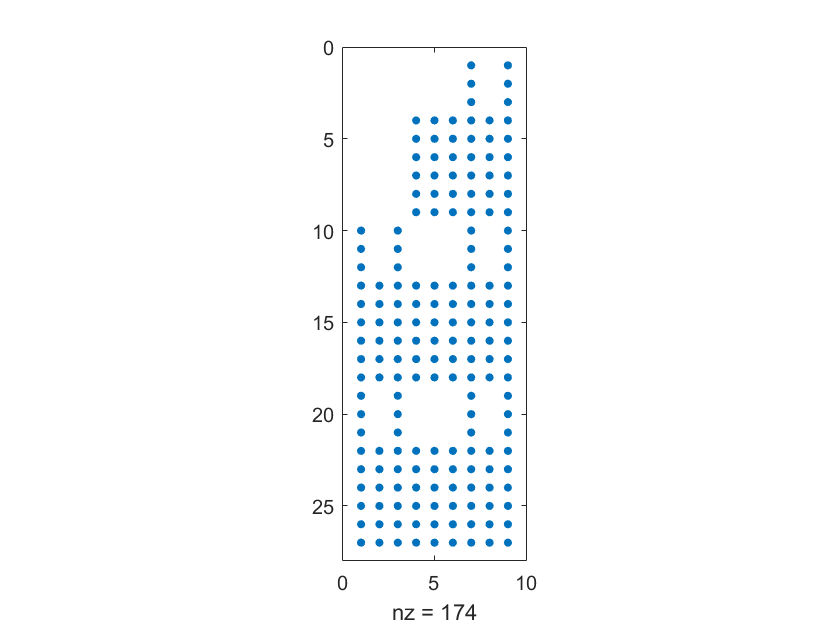

B = zeros(27, 9);
Q1 = zeros(3, 27);
Q2 = Q1;
for i = 0:2
    for j = 0:2
        for k = 0:2
            idx = k+j*3+i*9+1;
            Q = [i;j;10+10*k;1];
            q1 = project(Q, R, t1); % projection
            Q1(:, idx) = q1; % store the points
            q2 = project(Q, R, t2); % projection
            Q2(:, idx)=q2;
            B(idx, :) = kron(q1',q2');
        end
    end
end
spy(B)

[~,~,V] = svd(B);
f = V(:,end); % the last column of V
F = [f(1), f(4), f(7); f(2), f(5), f(8); f(3), f(6), f(9)]

F =    -0.0000    0.2626   -0.0000
   -0.2626    0.0000   -0.6565
   -0.0000    0.6565   -0.0000


## F

T1 = normal2(Q1)

T1 =    16.1645         0   -0.9878
         0   16.1645   -0.9878
         0         0    1.0000


T2 = normal2(Q2)

T2 =    12.5719         0    2.6826
         0   12.5719   -0.6707
         0         0    1.0000


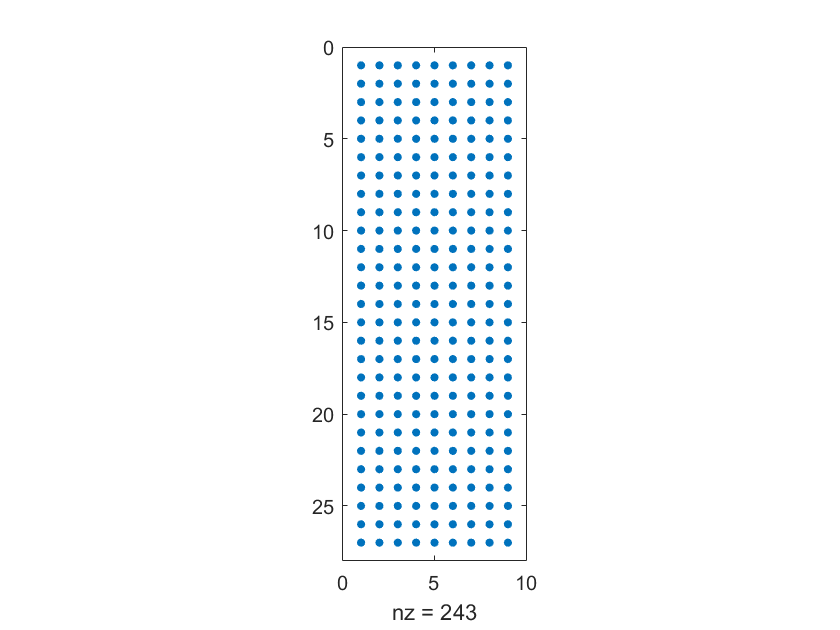

for i = 1:27
    q1 = T1*Q1(:,i);
    q2 = T2*Q2(:,i);
    B(i, :) = kron(q1', q2');
end
spy(B)

[~,~,v] = svd(B);
V = v(:, end);
F = [V(1), V(4), V(7); V(2), V(5), V(8); V(3), V(6), V(9)]

F =          0    0.0198    0.0196
   -0.0198    0.0000   -0.8208
   -0.0133    0.5699    0.0125


F = T2'*F*T1

F =          0    4.0290   -0.0000
   -4.0290    0.0000  -10.0725
   -0.0000   10.0725    0.0000


## G

B = zeros(27, 9);
Q1 = zeros(3, 27);
Q2 = Q1;
for i = 0:2
    for j = 0:2
        for k = 0:2
            idx = k+j*3+i*9+1;
            Q = [i;j+10*k;10;1];
            q1 = project(Q, R, t1); % projection
            Q1(:, idx) = q1; % store the points
            q2 = project(Q, R, t2); % projection
            Q2(:, idx)=q2;
        end
    end
end
T1 = normal2(Q1)

T1 =     1.7150         0   -0.1715
         0    1.7150   -1.8865
         0         0    1.0000


T2 = normal2(Q2)

T2 =     2.0580         0    0.6860
         0    2.0580   -1.8865
         0         0    1.0000


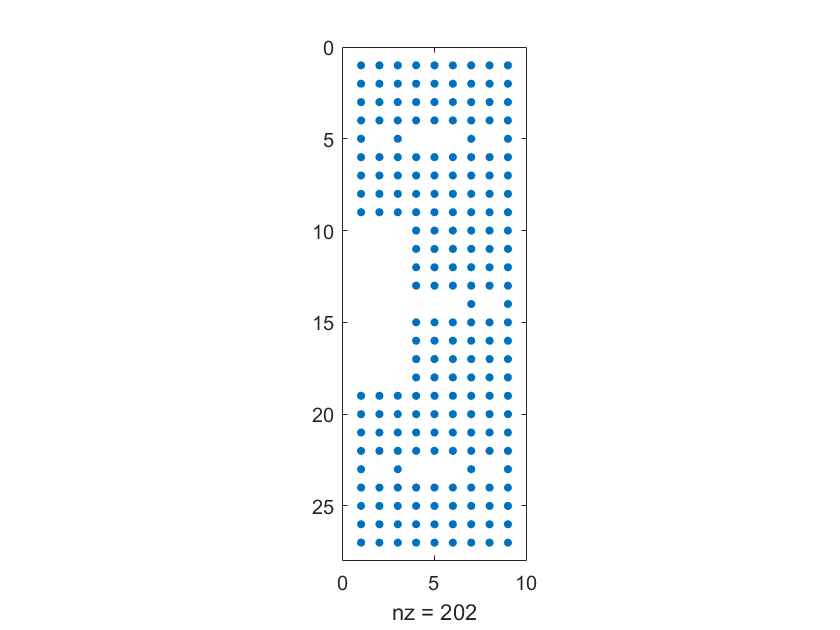

for i = 1:27
    q1 = T1*Q1(:,i);
    q2 = T2*Q2(:,i);
    B(i, :) = kron(q1', q2');
end
spy(B)% from B, we can know that this is an ill condition

[~,~,v] = svd(B);
V = v(:, end);
F = [V(1), V(4), V(7); V(2), V(5), V(8); V(3), V(6), V(9)]

F =     0.0000   -0.1505   -0.6909
    0.1505   -0.0000    0.0048
    0.6909   -0.0048   -0.0000


F = T2'*F*T1

F =     0.0000   -0.5313   -0.8373
    0.5313   -0.0000   -0.0432
    0.6978   -0.1854   -0.3489


## H

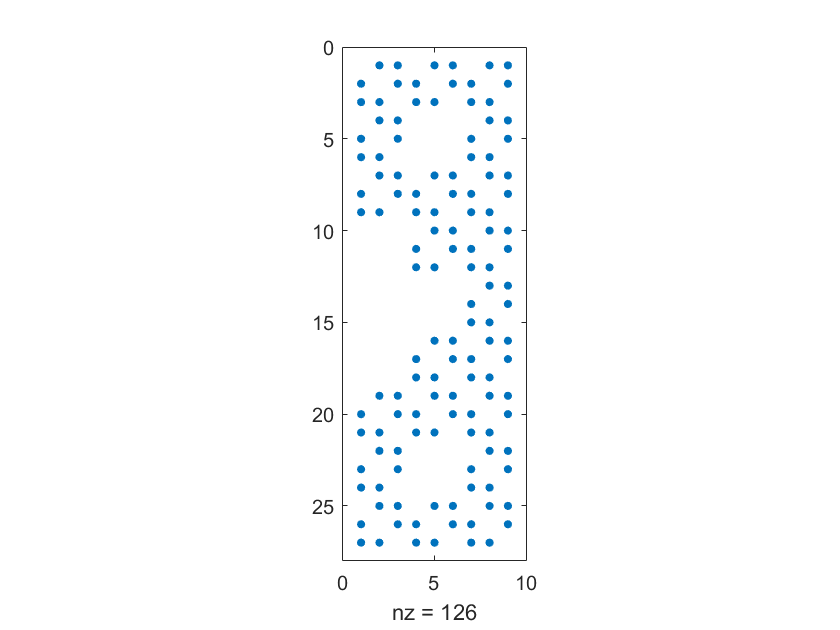

% firstly, generate the points
Q = zeros(9,3);
Q1 = zeros(3,9);
Q2 = zeros(3,9);
for i = 0:2
    for j = 0:2
        idx = i*3+j+1;
        Q = [i;j;10;1];
        q1 = project(Q, R, t1);
        q2 = project(Q, R, t2);
        Q1(:, idx) = q1;
        Q2(:, idx) = q2;
    end
end
T1 = normal2(Q1);
T2 = normal2(Q2);
B = zeros(27, 9);
for idx = 1:9
    q1 = T1*Q1(:, idx);
    q2 = T2*Q2(:, idx);
    x1 = q1(1);
    y1 = q1(2);
    x2 = q2(1);
    y2 = q2(2);
    B((idx-1)*3+1:idx*3, :) = [0, -x2, x2*y1, 0, -y2, y2*y1, 0, -1, y1;
        x2, 0, -x2*x1, y2, 0, -y2*x1, 1, 0, -x1;
        -x2*y1, x2*x1, 0, -y2*y1, y2*x1, 0, -y1, x1, 0];
end
spy(B);

[~, ~, V] = svd(B);
H = V(:,end);
H = [H(1), H(4), H(7); H(2), H(5), H(8); H(3), H(6), H(9)];
H = inv(T1)*H*T2;
H = H/abs(det(H))^(1/3)*(det(H))/abs(det(H))

H =     1.0627   -0.0000    0.4428
   -0.0000    1.0627    0.0000
   -0.0000   -0.0000    0.8855


det(H)

ans = 1.0000

%H = [-0.763, 0. 0.382;0. -0.763, 0;0,0,-0.916];
error = zeros(9, 1);
Q3 = H*Q2;
Q3 = Q3/Q3(3,1);
for i = 1:9
    e = abs(Q1(:,i)-Q3(:,i));
    error(i) = sqrt(e(1)^2+e(2)^2);
end
error

error = 	1.0e+-15 *

    0.1280
    0.1284
    0.1284
    0.0610
    0.0621
    0.0621
    0.0250
    0.0278
    0.0278


mean(error)

ans = 7.2263e-17